## Validate Protected Model

Folder: FMU_liv/EC_ctrl/test_harness

% Open model Controller
model = "EC_control";
open_system(model);

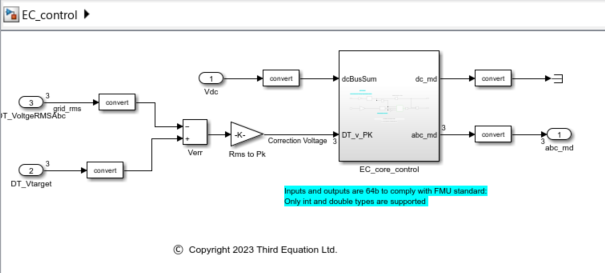

From **Simulation** tab select **Save** **> Save As..**. A dialog box opens where user can go to the *EC_ctrl\test_harness* folder and set the File name as *EC_control_harness*.

From the **Library Browser** add a *Model* block (Library>Simulink>Ports & Subsystems>Model). Double click on it and select the  *EC_ctrl\EC_core_control.slp *protected model in* Model name.*

Modify the model as shown in the following figure:

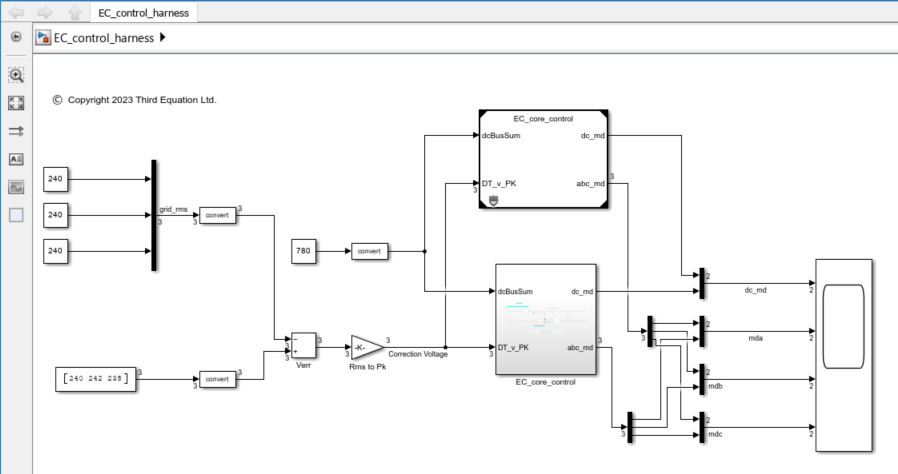

Note the *convert* blocks. They are included as the EC_core_control works with single presicion floats (32b)

Validation Requirement: Both blocks should deliver similar outputs when stimulated with similar inputs.

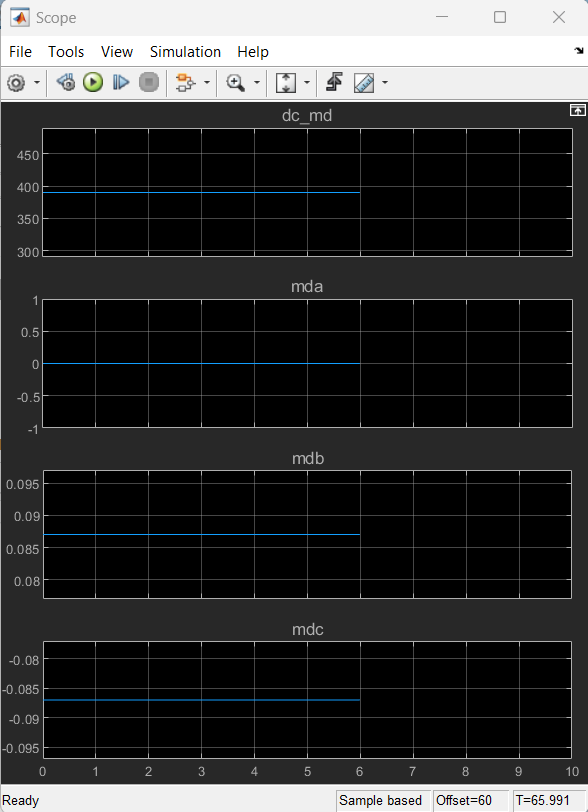

% close model after protected model is validated
close_system("EC_control_harness");

*Copyright 2024 Third Edquation Ltd.*